clear; clc; close all;

%% =========================================================
% Fast numerical workspace estimation
% - Gripper z-axis is forced vertically downward
% - Gripper y-axis is aligned with y0
% - Base is at (0,0), i.e. the middle of the chessboard edge
% - True chessboard length is shown on XY / YZ / ZX plots
%% =========================================================

%% =========================
% Robot dimensions
%% =========================
b  = 2.5;
L1 = 5;
L2 = 18;
L3 = 12;
L4 = 6;

%% =========================
% Chessboard parameters
% Base at x = 0, y = 0
% Chessboard spans:
%   x in [0, 30]
%   y in [-15, 15]
%% =========================
board_size   = 30;
board_x_min  = 3;
board_y_min  = -board_size/2;
board_z      = 0;

piece_height = 4;
lift_height  = 2 * piece_height;

%% =========================
% Joint ranges
% Independent joints: q1, q2, q3
% q4 and q5 are constrained by orientation requirements
%% =========================
q1_range = deg2rad(-90:1:90);
q2_range = deg2rad(-140:1:0);
q3_range = deg2rad(-140:1:0);

%% =========================
% Plane tolerances
%% =========================
z_tol = 0.5;   % XY plane at z = board_z
x_tol = 0.5;   % YZ plane at x = 0
y_tol = 0.5;   % ZX plane at y = 0

%% =========================
% Preallocation
%% =========================
n1 = numel(q1_range);
n2 = numel(q2_range);
n3 = numel(q3_range);

N = n1 * n2 * n3;
fprintf('Total sampled poses = %d\n', N);

Total sampled poses = 3598461



all_positions = zeros(N, 3);

%% =========================================================
% Nested loops
%% =========================================================
idx = 0;

for i1 = 1:n1
    for i2 = 1:n2
        for i3 = 1:n3

            %% =========================
            % Joint values for this sample
            %% =========================
            q = zeros(1,5);
            q(1) = q1_range(i1);
            q(2) = q2_range(i2);
            q(3) = q3_range(i3);

            % Orientation constraints:
            % 1) z5 always points downward
            % 2) y5 always aligns with y0
            q(4) = pi - q(2) - q(3);
            q(5) = q(1);

            %% =========================
            % Manual DH table
            %% =========================
            DH_table = [ ...
               -b,   pi/2,   L1,      q(1);
                L2,    0,     0,      q(2) + pi/2;
                L3,    0,     0,      q(3);
                 0,   -pi/2,  0,      pi - q(2) - q(3) - pi/2;
                 0,    0,    L4,      q(1)
            ];

            %% =========================
            % Forward kinematics
            %% =========================
            T = eye(4);

            for k = 1:5
                a     = DH_table(k,1);
                alpha = DH_table(k,2);
                d     = DH_table(k,3);
                theta = DH_table(k,4);

                A = DH_std(a, alpha, d, theta);
                T = T * A;
            end

            p = T(1:3,4);

            idx = idx + 1;
            all_positions(idx,:) = p.';
        end
    end
end

%% =========================
% Trim unused rows
%% =========================
all_positions = all_positions(1:idx,:);

if isempty(all_positions)
    error('No valid workspace points found.');
end

%% =========================
% Plane filtering
%% =========================
xy_mask = abs(all_positions(:,3) - board_z) <= z_tol;
xy_points = all_positions(xy_mask, :);

yz_mask = abs(all_positions(:,1)) <= x_tol;
yz_points = all_positions(yz_mask, :);

zx_mask = abs(all_positions(:,2)) <= y_tol;
zx_points = all_positions(zx_mask, :);

%% =========================================================
% Numerical summary
%% =========================================================
fprintf('Points near XY plane (z = %.2f cm) = %d\n', board_z, size(xy_points,1));

Points near XY plane (z = 0.00 cm) = 68056


fprintf('Points near YZ plane (x = 0 cm) = %d\n', size(yz_points,1));

Points near YZ plane (x = 0 cm) = 190409


fprintf('Points near ZX plane (y = 0 cm) = %d\n', size(zx_points,1));

Points near ZX plane (y = 0 cm) = 170739



fprintf('\nWorkspace bounds:\n');


Workspace bounds:


fprintf('x: [%.2f, %.2f] cm\n', min(all_positions(:,1)), max(all_positions(:,1)));

x: [-2.93, 27.50] cm


fprintf('y: [%.2f, %.2f] cm\n', min(all_positions(:,2)), max(all_positions(:,2)));

y: [-27.50, 27.50] cm


fprintf('z: [%.2f, %.2f] cm\n', min(all_positions(:,3)), max(all_positions(:,3)));

z: [-26.79, 29.00] cm


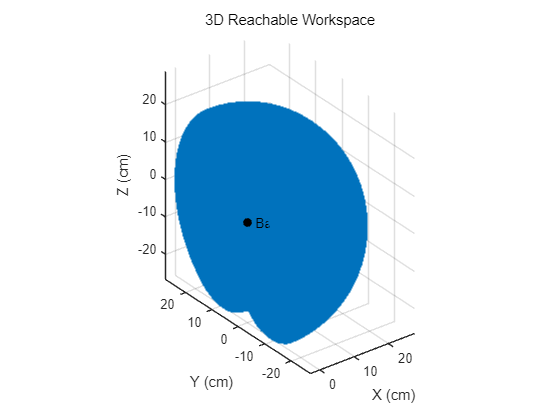


%% =========================================================
% Plot 1: 3D workspace
%% =========================================================
figure('Name','3D Workspace', 'NumberTitle','off');
scatter3(all_positions(:,1), all_positions(:,2), all_positions(:,3), 3, 'filled');
grid on; axis equal;
xlabel('X (cm)');
ylabel('Y (cm)');
zlabel('Z (cm)');
title('3D Reachable Workspace');
hold on;

plot3(0,0,0,'ko','MarkerFaceColor','k','MarkerSize',6);
text(0,0,0,'  Base');

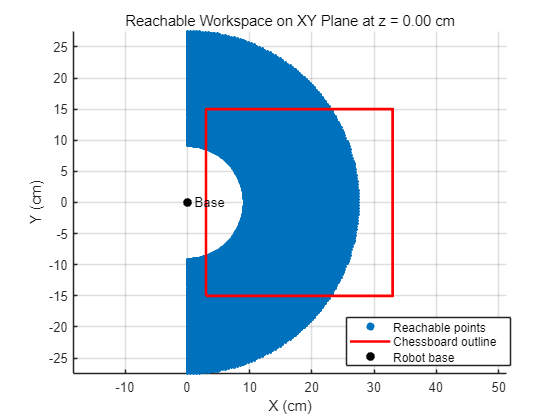


%% =========================================================
% Plot 2: XY workspace at chessboard height
%% =========================================================
figure('Name','XY Workspace', 'NumberTitle','off');
hold on; grid on; axis equal;

if ~isempty(xy_points)
    scatter(xy_points(:,1), xy_points(:,2), 5, 'filled');
end

board_x = [board_x_min, board_x_min + board_size, ...
           board_x_min + board_size, board_x_min, board_x_min];
board_y = [board_y_min, board_y_min, ...
           board_y_min + board_size, board_y_min + board_size, board_y_min];

plot(board_x, board_y, 'r-', 'LineWidth', 2);
plot(0,0,'ko','MarkerFaceColor','k','MarkerSize',6);
text(0,0,'  Base');

xlabel('X (cm)');
ylabel('Y (cm)');
title(sprintf('Reachable Workspace on XY Plane at z = %.2f cm', board_z));
legend('Reachable points', 'Chessboard outline', 'Robot base', 'Location', 'best');
legend("Position", [0.62643,0.12721,0.27679,0.11905])

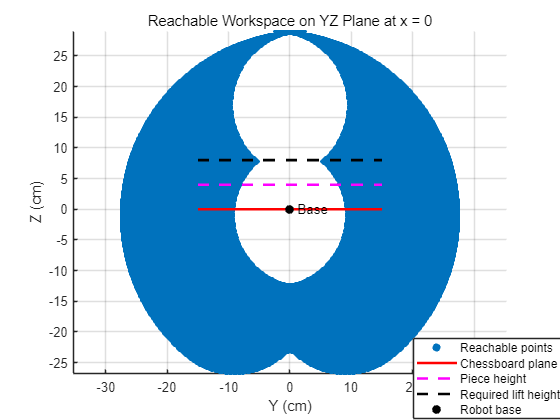


%% =========================================================
% Plot 3: YZ workspace at x = 0
%% =========================================================
figure('Name','YZ Workspace', 'NumberTitle','off');
hold on; grid on; axis equal;

if ~isempty(yz_points)
    scatter(yz_points(:,2), yz_points(:,3), 5, 'filled');
end

% True chessboard projection in YZ plane at x = 0
y_board_min = board_y_min;
y_board_max = board_y_min + board_size;

% Chessboard plane (true board length)
plot([y_board_min, y_board_max], [board_z, board_z], 'r-', 'LineWidth', 2);

% Chess piece height (true board length)
plot([y_board_min, y_board_max], [board_z + piece_height, board_z + piece_height], ...
    'm--', 'LineWidth', 2);

% Required lift height = 2 x piece height (true board length)
plot([y_board_min, y_board_max], [board_z + lift_height, board_z + lift_height], ...
    'k--', 'LineWidth', 2);

% Base centre point
plot(0,0,'ko','MarkerFaceColor','k','MarkerSize',6);
text(0,0,'  Base');

xlabel('Y (cm)');
ylabel('Z (cm)');
title('Reachable Workspace on YZ Plane at x = 0');
legend('Reachable points', 'Chessboard plane', 'Piece height', ...
       'Required lift height (2 x piece height)', 'Robot base', ...
       'Location', 'best');
legend("Position", [0.73805,0.0020238,0.44107,0.19286])

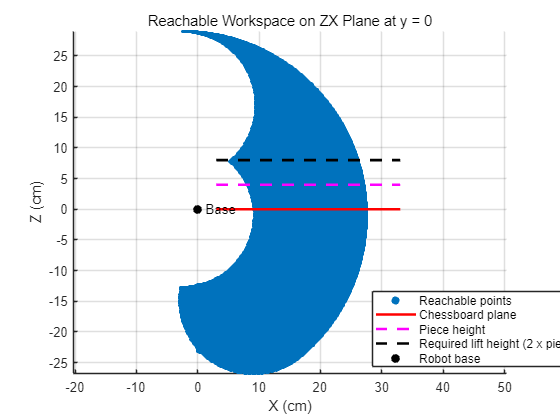


%% =========================================================
% Plot 4: ZX workspace at y = 0
%% =========================================================
figure('Name','ZX Workspace', 'NumberTitle','off');
hold on; grid on; axis equal;

if ~isempty(zx_points)
    scatter(zx_points(:,1), zx_points(:,3), 5, 'filled');
end

% True chessboard projection in ZX plane at y = 0
x_board_min = board_x_min;
x_board_max = board_x_min + board_size;

% Chessboard plane (true board length)
plot([x_board_min, x_board_max], [board_z, board_z], 'r-', 'LineWidth', 2);

% Chess piece height (true board length)
plot([x_board_min, x_board_max], [board_z + piece_height, board_z + piece_height], ...
    'm--', 'LineWidth', 2);

% Required lift height = 2 x piece height (true board length)
plot([x_board_min, x_board_max], [board_z + lift_height, board_z + lift_height], ...
    'k--', 'LineWidth', 2);

% Base centre point
plot(0,0,'ko','MarkerFaceColor','k','MarkerSize',6);
text(0,0,'  Base');

xlabel('X (cm)');
ylabel('Z (cm)');
title('Reachable Workspace on ZX Plane at y = 0');
legend('Reachable points', 'Chessboard plane', 'Piece height', ...
       'Required lift height (2 x piece height)', 'Robot base', ...
       'Location', 'best');
legend("Position", [0.67912,0.12107,0.44107,0.19286])


%% =========================================================
% Optional check: one sample tool axes
%% =========================================================
q = [0, -pi/2, 0, 0, 0];
q(4) = pi - q(2) - q(3);
q(5) = q(1);

DH_table_check = [ ...
   -b,   pi/2,   L1,      q(1);
    L2,    0,     0,      q(2) + pi/2;
    L3,    0,     0,      q(3);
     0,   -pi/2,  0,      pi - q(2) - q(3) - pi/2;
     0,    0,    L4,      q(1)
];

Tcheck = eye(4);
for k = 1:5
    A = DH_std(DH_table_check(k,1), DH_table_check(k,2), ...
               DH_table_check(k,3), DH_table_check(k,4));
    Tcheck = Tcheck * A;
end

R_tool = Tcheck(1:3,1:3);
x_tool = R_tool(:,1);
y_tool = R_tool(:,2);
z_tool = R_tool(:,3);

fprintf('\nSample tool x-axis = [%.4f %.4f %.4f]^T\n', x_tool(1), x_tool(2), x_tool(3));


Sample tool x-axis = [-1.0000 0.0000 0.0000]^T


fprintf('Sample tool y-axis = [%.4f %.4f %.4f]^T\n', y_tool(1), y_tool(2), y_tool(3));

Sample tool y-axis = [-0.0000 1.0000 -0.0000]^T


fprintf('Sample tool z-axis = [%.4f %.4f %.4f]^T\n', z_tool(1), z_tool(2), z_tool(3));

Sample tool z-axis = [-0.0000 -0.0000 -1.0000]^T



%% =========================================================
% Standard DH transform
%% =========================================================

function T = DH_std(a, alpha, d, theta)
ct = cos(theta);  st = sin(theta);
ca = cos(alpha);  sa = sin(alpha);

T = [ct, -st*ca,  st*sa, a*ct;
     st,  ct*ca, -ct*sa, a*st;
     0,      sa,     ca,    d;
     0,       0,      0,    1];
end
























% clear; clc; close all;
% 
% %% =========================================================
% % Fast numerical workspace estimation
% % - Gripper is forced to point vertically downward
% % - Base is at the centre of the chessboard
% % - Base point is shown on XY / YZ / ZX plots
% % - DH table is written in the exact form requested
% %% =========================================================
% 
% %% =========================
% % Robot dimensions
% %% =========================
% b  = 2.5;
% L1 = 5;
% L2 = 18;
% L3 = 12;
% L4 = 6;
% 
% %% =========================
% % Chessboard parameters
% % Base at the centre of the chessboard
% % So board spans:
% %   x in [-15, 15]
% %   y in [-15, 15]
% %% =========================
% board_size   = 30;
% board_x_min  = 0;
% board_y_min  = -board_size/2;
% board_z      = 0;
% 
% piece_height = 4;
% lift_height  = 2 * piece_height;
% 
% %% =========================
% % Joint ranges
% % q4 is NOT independently swept anymore
% % because gripper is forced downward by DH row 4
% %% =========================
% q1_range = deg2rad(-90:1:90);
% q2_range = deg2rad(-140:1:0);
% q3_range = deg2rad(-140:1:0);
% 
% % q5 does not affect position in this model, so not swept
% q5_value = 0;
% 
% %% =========================
% % Plane tolerances
% %% =========================
% z_tol = 0.5;   % for XY plane at z = board_z
% x_tol = 0.5;   % for YZ plane at x = 0
% y_tol = 0.5;   % for ZX plane at y = 0
% 
% %% =========================
% % Preallocation
% %% =========================
% n1 = numel(q1_range);
% n2 = numel(q2_range);
% n3 = numel(q3_range);
% 
% N = n1 * n2 * n3;
% fprintf('Total sampled poses = %d\n', N);
% 
% all_positions = zeros(N, 3);
% 
% %% =========================================================
% % Nested loops
% %% =========================================================
% idx = 0;
% 
% for i1 = 1:n1
%     for i2 = 1:n2
%         for i3 = 1:n3
% 
%             %% =========================
%             % Joint values for this sample
%             %% =========================
%             q = zeros(1,5);
%             q(1) = q1_range(i1);
%             q(2) = q2_range(i2);
%             q(3) = q3_range(i3);
%             q(5) = q5_value;
% 
%             %% =========================
%             % Manual DH table
%             % EXACTLY in the format you requested
%             %% =========================
%             DH_table = [ ...
%                -b,   pi/2,   L1,      q(1);
%                 L2,    0,     0,      q(2) + pi/2;
%                 L3,    0,     0,      q(3);
%                  0,   -pi/2,  0,      pi - q(2) - q(3) - pi/2;
%                  0,    0,    L4,      q(1)
%             ];
% 
%             %% =========================
%             % Forward kinematics
%             %% =========================
%             T = eye(4);
% 
%             % Multiply first 4 rows first
%             % Then use row 5 implicitly as tool offset along z4
%             for k = 1:4
%                 a     = DH_table(k,1);
%                 alpha = DH_table(k,2);
%                 d     = DH_table(k,3);
%                 theta = DH_table(k,4);
% 
%                 A = DH_std(a, alpha, d, theta);
%                 T = T * A;
%             end
% 
%             % End-effector position:
%             % row 5 = [0,0,L4,q5], and q5 rotation does not affect position
%             p = T(1:3,4) + L4 * T(1:3,3);
% 
%             idx = idx + 1;
%             all_positions(idx,:) = p.';
%         end
%     end
% end
% 
% %% =========================
% % Trim unused rows
% %% =========================
% all_positions = all_positions(1:idx,:);
% 
% if isempty(all_positions)
%     error('No valid workspace points found.');
% end
% 
% %% =========================
% % Plane filtering
% %% =========================
% % XY plane at chessboard height
% xy_mask = abs(all_positions(:,3) - board_z) <= z_tol;
% xy_points = all_positions(xy_mask, :);
% 
% % YZ plane at x = 0
% yz_mask = abs(all_positions(:,1)) <= x_tol;
% yz_points = all_positions(yz_mask, :);
% 
% % ZX plane at y = 0
% zx_mask = abs(all_positions(:,2)) <= y_tol;
% zx_points = all_positions(zx_mask, :);
% 
% %% =========================================================
% % Numerical summary
% %% =========================================================
% fprintf('Points near XY plane (z = %.2f cm) = %d\n', board_z, size(xy_points,1));
% fprintf('Points near YZ plane (x = 0 cm) = %d\n', size(yz_points,1));
% fprintf('Points near ZX plane (y = 0 cm) = %d\n', size(zx_points,1));
% 
% fprintf('\nWorkspace bounds:\n');
% fprintf('x: [%.2f, %.2f] cm\n', min(all_positions(:,1)), max(all_positions(:,1)));
% fprintf('y: [%.2f, %.2f] cm\n', min(all_positions(:,2)), max(all_positions(:,2)));
% fprintf('z: [%.2f, %.2f] cm\n', min(all_positions(:,3)), max(all_positions(:,3)));
% 
% %% =========================================================
% % Plot 1: 3D workspace
% %% =========================================================
% figure('Name','3D Workspace', 'NumberTitle','off');
% scatter3(all_positions(:,1), all_positions(:,2), all_positions(:,3), 3, 'filled');
% grid on; axis equal;
% xlabel('X (cm)');
% ylabel('Y (cm)');
% zlabel('Z (cm)');
% title('3D Reachable Workspace (Gripper Forced Downward)');
% hold on;
% 
% plot3(0,0,0,'ko','MarkerFaceColor','k','MarkerSize',6);
% text(0,0,0,'  Base');
% 
% %% =========================================================
% % Plot 2: XY workspace at chessboard height
% %% =========================================================
% figure('Name','XY Workspace', 'NumberTitle','off');
% hold on; grid on; axis equal;
% 
% if ~isempty(xy_points)
%     scatter(xy_points(:,1), xy_points(:,2), 5, 'filled');
% end
% 
% board_x = [board_x_min, board_x_min + board_size, ...
%            board_x_min + board_size, board_x_min, board_x_min];
% board_y = [board_y_min, board_y_min, ...
%            board_y_min + board_size, board_y_min + board_size, board_y_min];
% 
% plot(board_x, board_y, 'r-', 'LineWidth', 2);
% plot(0,0,'ko','MarkerFaceColor','k','MarkerSize',6);
% text(0,0,'  Base');
% 
% xlabel('X (cm)');
% ylabel('Y (cm)');
% title(sprintf('Reachable Workspace on XY Plane at z = %.2f cm', board_z));
% legend('Reachable points', 'Chessboard outline', 'Robot base', 'Location', 'best');
% 
% legend("Position", [0.62643,0.12721,0.27679,0.11905])
% 
% %% =========================================================
% % Plot 3: YZ workspace at x = 0
% %% =========================================================
% figure('Name','YZ Workspace', 'NumberTitle','off');
% hold on; grid on; axis equal;
% 
% if ~isempty(yz_points)
%     scatter(yz_points(:,2), yz_points(:,3), 5, 'filled');
% end
% 
% y_min_plot = min(all_positions(:,2)) - 2;
% y_max_plot = max(all_positions(:,2)) + 2;
% 
% % Chessboard plane
% plot([y_min_plot, y_max_plot], [board_z, board_z], 'r-', 'LineWidth', 2);
% 
% % Chess piece height
% plot([y_min_plot, y_max_plot], [board_z + piece_height, board_z + piece_height], ...
%     'm--', 'LineWidth', 2);
% 
% % Required lift height = 2 x piece height
% plot([y_min_plot, y_max_plot], [board_z + lift_height, board_z + lift_height], ...
%     'k--', 'LineWidth', 2);
% 
% % Base centre point
% plot(0,0,'ko','MarkerFaceColor','k','MarkerSize',6);
% text(0,0,'  Base');
% 
% xlabel('Y (cm)');
% ylabel('Z (cm)');
% title('Reachable Workspace on YZ Plane at x = 0');
% legend('Reachable points', 'Chessboard plane', 'Piece height', ...
%        'Required lift height (2 x piece height)', 'Robot base', ...
%        'Location', 'best');
% 
% legend("Position", [0.73805,0.0020238,0.44107,0.19286])
% 
% %% =========================================================
% % Plot 4: ZX workspace at y = 0
% %% =========================================================
% figure('Name','ZX Workspace', 'NumberTitle','off');
% hold on; grid on; axis equal;
% 
% if ~isempty(zx_points)
%     scatter(zx_points(:,1), zx_points(:,3), 5, 'filled');
% end
% 
% x_min_plot = min(all_positions(:,1)) - 2;
% x_max_plot = max(all_positions(:,1)) + 2;
% 
% % Chessboard plane
% plot([x_min_plot, x_max_plot], [board_z, board_z], 'r-', 'LineWidth', 2);
% 
% % Chess piece height
% plot([x_min_plot, x_max_plot], [board_z + piece_height, board_z + piece_height], ...
%     'm--', 'LineWidth', 2);
% 
% % Required lift height = 2 x piece height
% plot([x_min_plot, x_max_plot], [board_z + lift_height, board_z + lift_height], ...
%     'k--', 'LineWidth', 2);
% 
% % Base centre point
% plot(0,0,'ko','MarkerFaceColor','k','MarkerSize',6);
% text(0,0,'  Base');
% 
% xlabel('X (cm)');
% ylabel('Z (cm)');
% title('Reachable Workspace on ZX Plane at y = 0');
% legend('Reachable points', 'Chessboard plane', 'Piece height', ...
%        'Required lift height (2 x piece height)', 'Robot base', ...
%        'Location', 'best');
% 
% legend("Position", [0.67912,0.12107,0.44107,0.19286])
% 
% %% =========================================================
% % Optional check: one sample tool z-axis
% %% =========================================================
% q = [0, -pi/2, 0, 0, q5_value];
% 
% DH_table_check = [ ...
%    -b,   pi/2,   L1,      q(1);
%     L2,    0,     0,      q(2) + pi/2;
%     L3,    0,     0,      q(3);
%      0,   -pi/2,  0,      pi - q(2) - q(3) - pi/2;
%      0,    0,    L4,      q(1)
% ];
% 
% Tcheck = eye(4);
% for k = 1:4
%     A = DH_std(DH_table_check(k,1), DH_table_check(k,2), ...
%                DH_table_check(k,3), DH_table_check(k,4));
%     Tcheck = Tcheck * A;
% end
% 
% z_tool = Tcheck(1:3,3);
% fprintf('\nSample tool z-axis = [%.4f %.4f %.4f]^T\n', z_tool(1), z_tool(2), z_tool(3));
% 
% %% =========================================================
% % Standard DH transform
% %% =========================================================
% function T = DH_std(a, alpha, d, theta)
% ct = cos(theta);  st = sin(theta);
% ca = cos(alpha);  sa = sin(alpha);
% 
% T = [ct, -st*ca,  st*sa, a*ct;
%      st,  ct*ca, -ct*sa, a*st;
%      0,      sa,     ca,    d;
%      0,       0,      0,    1];
% end